HW3P6

Bullet 3: They Match up, Perfect!

% Analytic Solution
f = @(t) -sin(2*t) + t^2 -3; 

% Bounds of Solution
tspan = [0 2];

% Initial Vector
y0 = [-3; -2; 2];

% Ode Solution
[t,y] = ode113(@odefun, tspan, y0);

figure(1);
plot(t,y(:,1),"b");
hold on;
fplot(f,tspan,"g");

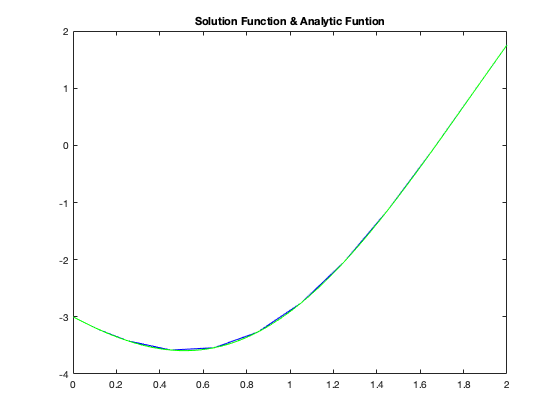

title("Solution Function & Analytic Funtion");

Bullet 4: Adams-Batchforth

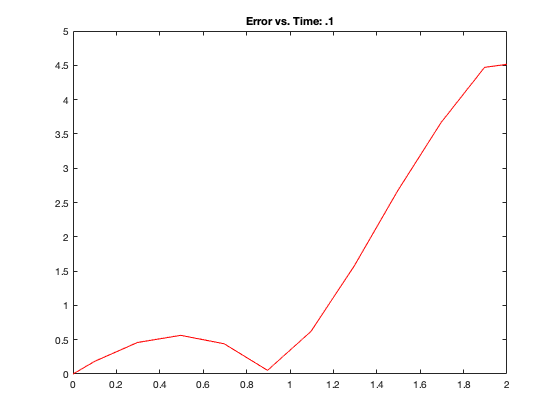


% Analytic Solution
f = @(t) -sin(2*t) + t^2 -3; 

% Bounds of Solution
tspan = [0 2];

% Initial Vector
y0 = [-3; -2; 2];

%Setting Different Tolerance options
options1 = odeset('AbsTol',.1);
options2 = odeset('AbsTol',.01);
options3 = odeset('AbsTol',.001);
options4 = odeset('AbsTol',.0001);
options5 = odeset('AbsTol',.00001);

% Ode Solutions With Different Specifications of Tolerance
[t1,y1] = ode113(@odefun, tspan, y0,options1);
[t2,y2] = ode113(@odefun, tspan, y0,options2);
[t3,y3] = ode113(@odefun, tspan, y0,options3);
[t4,y4] = ode113(@odefun, tspan, y0,options4);
[t5,y5] = ode113(@odefun, tspan, y0,options5);

% Make Error Vectors
error1 = zeros(length(t1),2);
error2 = zeros(length(t2),2);
error3 = zeros(length(t3),2);
error4 = zeros(length(t4),2);
error5 = zeros(length(t5),2);

% Make Time Stamps
error1(:,1) = t1;
error2(:,1) = t2;
error3(:,1) = t3;
error4(:,1) = t4;
error5(:,1) = t5;

% Construct Error1 Data
for i = 1: length(error1)
    
    error1(i,2) = abs(f(error1(i,1)) - y(i));
end

% Construct Error2 Data
for i = 1: length(error2)
    
    error2(i,2) = abs(f(error2(i,1)) - y(i));
end

% Construct Error3 Data
for i = 1: length(error3)
    
    error3(i,2) = abs(f(error3(i,1)) - y(i));
end

% Construct Error4 Data
for i = 1: length(error4)
    
    error4(i,2) = abs(f(error4(i,1)) - y(i));
end

% Construct Error5 Data
for i = 1: length(error5)
    
    error5(i,2) = abs(f(error5(i,1)) - y(i));
end


% Initial For Opt Loop 1
maxE1 = error1(1,2);
index1 = error1(1,1);

% Find Max Error
for i = 1: length(error1)
   
    if(error1(i,2) >= maxE1)
        
        maxE1 = error1(i,2);
        index1 = i;
    end
end

% Initial For Opt Loop 2
maxE2 = error2(1,2);
index2 = error2(1,1);

% Find Max Error
for i = 1: length(error2)
   
    if(error2(i,2) >= maxE2)
        
        maxE2 = error2(i,2);
        index2 = i;
    end
end

% Initial For Opt Loop 3
maxE3 = error3(1,2);
index3 = error3(1,1);

% Find Max Error
for i = 1: length(error3)
   
    if(error3(i,2) >= maxE3)
        
        maxE3 = error3(i,2);
        index3 = i;
    end
end

% Initial For Opt Loop 4
maxE4 = error4(1,2);
index4 = error4(1,1);

% Find Max Error
for i = 1: length(error4)
   
    if(error4(i,2) >= maxE4)
        
        maxE4 = error4(i,2);
        index4 = i;
    end
end

% Initial For Opt Loop 5
maxE5 = error5(1,2);
index5 = error5(1,1);

% Find Max Error
for i = 1: length(error5)
   
    if(error5(i,2) >= maxE5)
        
        maxE5 = error5(i,2);
        index5 = i;
    end
end

% Plot Error V. Time For .1
clf;
figure(2);
plot(error1(:,1),error1(:,2),"r");
title("Error vs. Time: .1");

disp("Max Error .1 is: " + maxE1);

Max Error .1 is: 4.5145


disp("We took " + length(error1(:,1)) + " steps to get there");

We took 12 steps to get there


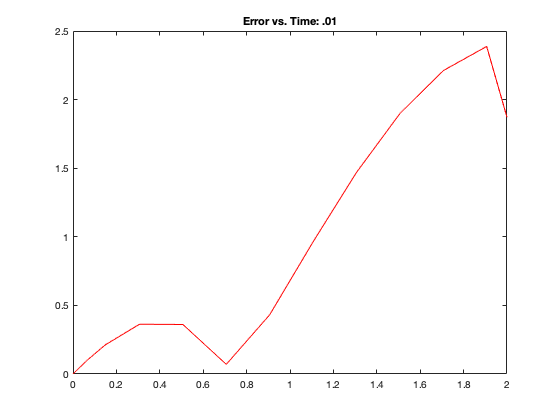


% Plot Error V. Time For .01
clf;
figure(3);
plot(error2(:,1),error2(:,2),"r");
title("Error vs. Time: .01");

disp("Max Error .01 is: " + maxE2);

Max Error .01 is: 2.3876


disp("We took " + length(error2(:,1)) + " steps to get there");

We took 15 steps to get there


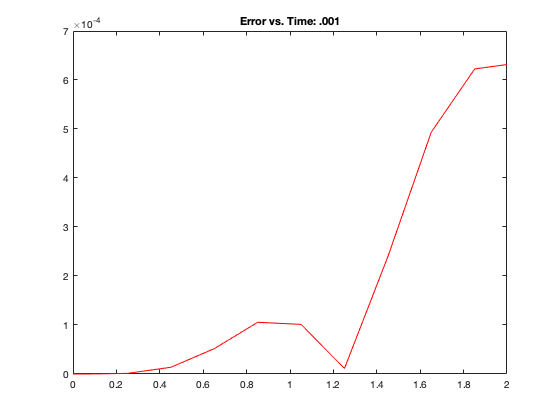


% Plot Error V. Time For .001
clf;
figure(4);
plot(error3(:,1),error3(:,2),"r");
title("Error vs. Time: .001");

disp("Max Error .001 is: " + maxE3);

Max Error .001 is: 0.00063159


disp("We took " + length(error3(:,1)) + " steps to get there");

We took 17 steps to get there


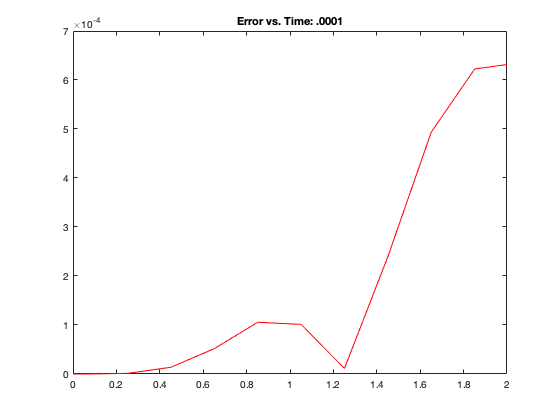


% Plot Error V. Time For .0001
clf;
figure(5);
plot(error4(:,1),error4(:,2),"r");
title("Error vs. Time: .0001");

disp("Max Error .0001 is: " + maxE4);

Max Error .0001 is: 0.00063159


disp("We took " + length(error4(:,1)) + " steps to get there");

We took 17 steps to get there


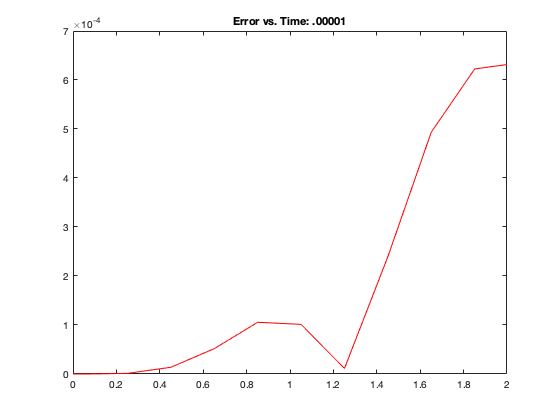


% Plot Error V. Time For .00001
clf;
figure(6);
plot(error5(:,1),error5(:,2),"r");
title("Error vs. Time: .00001");

disp("Max Error .00001 is: " + maxE5);

Max Error .00001 is: 0.00063159


disp("We took " + length(error5(:,1)) + " steps to get there");

We took 17 steps to get there


Bullet 5: Runge Kutte: All Code is The Same As Above (save for what ode solver is used) so data from previous variables have been overwritten. Nonetheless, the graphs come out according to what has been requested.

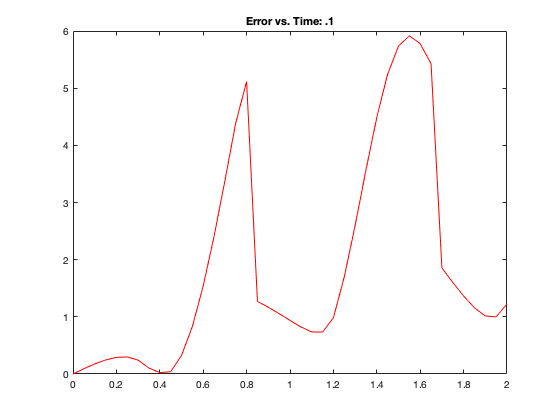


% Analytic Solution
f = @(t) -sin(2*t) + t^2 -3; 

% Bounds of Solution
tspan = [0 2];

% Initial Vector
y0 = [-3; -2; 2];

%Setting Different Tolerance options
options1 = odeset('AbsTol',.1);
options2 = odeset('AbsTol',.01);
options3 = odeset('AbsTol',.001);
options4 = odeset('AbsTol',.0001);
options5 = odeset('AbsTol',.00001);

% Ode Solutions With Different Specifications of Tolerance
[t1,y1] = ode45(@odefun, tspan, y0,options1);
[t2,y2] = ode45(@odefun, tspan, y0,options2);
[t3,y3] = ode45(@odefun, tspan, y0,options3);
[t4,y4] = ode45(@odefun, tspan, y0,options4);
[t5,y5] = ode45(@odefun, tspan, y0,options5);

% Make Error Vectors
error1 = zeros(length(t1),2);
error2 = zeros(length(t2),2);
error3 = zeros(length(t3),2);
error4 = zeros(length(t4),2);
error5 = zeros(length(t5),2);

% Make Time Stamps
error1(:,1) = t1;
error2(:,1) = t2;
error3(:,1) = t3;
error4(:,1) = t4;
error5(:,1) = t5;

% Construct Error1 Data
for i = 1: length(error1)
    
    error1(i,2) = abs(f(error1(i,1)) - y(i));
end

% Construct Error2 Data
for i = 1: length(error2)
    
    error2(i,2) = abs(f(error2(i,1)) - y(i));
end

% Construct Error3 Data
for i = 1: length(error3)
    
    error3(i,2) = abs(f(error3(i,1)) - y(i));
end

% Construct Error4 Data
for i = 1: length(error4)
    
    error4(i,2) = abs(f(error4(i,1)) - y(i));
end

% Construct Error5 Data
for i = 1: length(error5)
    
    error5(i,2) = abs(f(error5(i,1)) - y(i));
end


% Initial For Opt Loop 1
maxE1 = error1(1,2);
index1 = error1(1,1);

% Find Max Error
for i = 1: length(error1)
   
    if(error1(i,2) >= maxE1)
        
        maxE1 = error1(i,2);
        index1 = i;
    end
end

% Initial For Opt Loop 2
maxE2 = error2(1,2);
index2 = error2(1,1);

% Find Max Error
for i = 1: length(error2)
   
    if(error2(i,2) >= maxE2)
        
        maxE2 = error2(i,2);
        index2 = i;
    end
end

% Initial For Opt Loop 3
maxE3 = error3(1,2);
index3 = error3(1,1);

% Find Max Error
for i = 1: length(error3)
   
    if(error3(i,2) >= maxE3)
        
        maxE3 = error3(i,2);
        index3 = i;
    end
end

% Initial For Opt Loop 4
maxE4 = error4(1,2);
index4 = error4(1,1);

% Find Max Error
for i = 1: length(error4)
   
    if(error4(i,2) >= maxE4)
        
        maxE4 = error4(i,2);
        index4 = i;
    end
end

% Initial For Opt Loop 5
maxE5 = error5(1,2);
index5 = error5(1,1);

% Find Max Error
for i = 1: length(error5)
   
    if(error5(i,2) >= maxE5)
        
        maxE5 = error5(i,2);
        index5 = i;
    end
end

% Plot Error V. Time For .1
clf;
figure(7);
plot(error1(:,1),error1(:,2),"r");
title("Error vs. Time: .1");

disp("Max Error .1 is: " + maxE1);

Max Error .1 is: 5.9162


disp("We took " + length(error1(:,1)) + " steps to get there");

We took 41 steps to get there


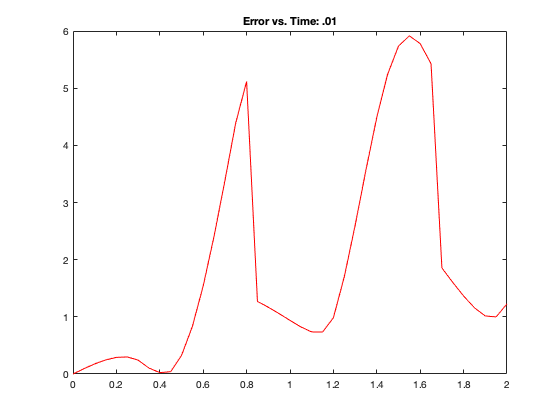


% Plot Error V. Time For .01
clf;
figure(8);
plot(error2(:,1),error2(:,2),"r");
title("Error vs. Time: .01");

disp("Max Error .01 is: " + maxE2);

Max Error .01 is: 5.9162


disp("We took " + length(error2(:,1)) + " steps to get there");

We took 41 steps to get there


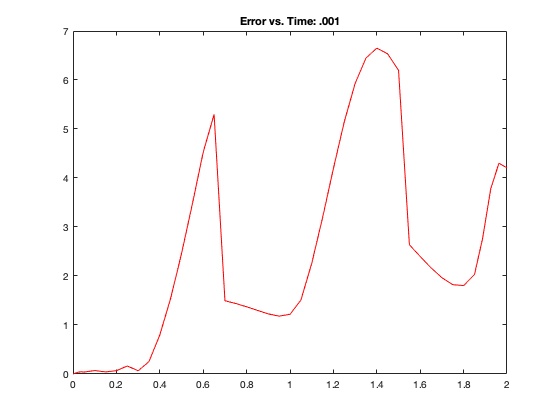


% Plot Error V. Time For .001
clf;
figure(9);
plot(error3(:,1),error3(:,2),"r");
title("Error vs. Time: .001");

disp("Max Error .001 is: " + maxE3);

Max Error .001 is: 6.651


disp("We took " + length(error3(:,1)) + " steps to get there");

We took 45 steps to get there


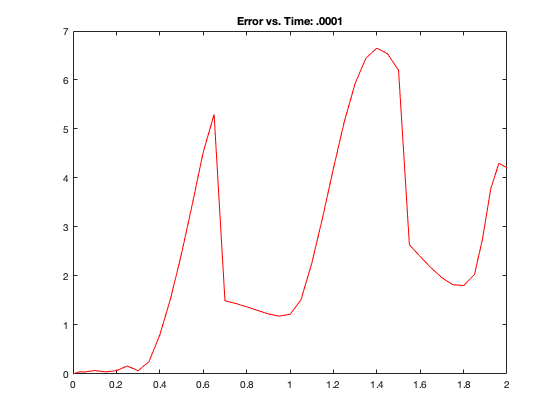


% Plot Error V. Time For .0001
clf;
figure(10);
plot(error4(:,1),error4(:,2),"r");
title("Error vs. Time: .0001");

disp("Max Error .0001 is: " + maxE4);

Max Error .0001 is: 6.651


disp("We took " + length(error4(:,1)) + " steps to get there");

We took 45 steps to get there


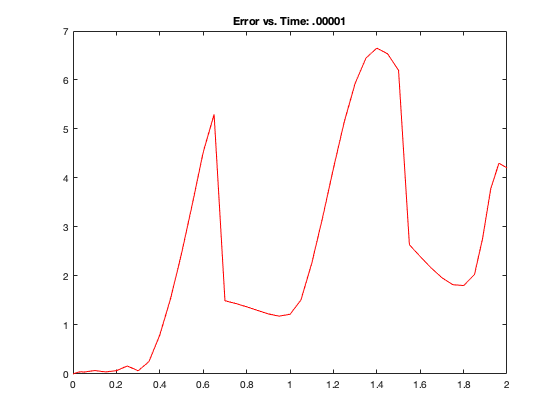


% Plot Error V. Time For .00001
clf;
figure(11);
plot(error5(:,1),error5(:,2),"r");
title("Error vs. Time: .00001");

disp("Max Error .00001 is: " + maxE5);

Max Error .00001 is: 6.651


disp("We took " + length(error5(:,1)) + " steps to get there");

We took 45 steps to get there


function dydt = odefun(t,y)

dydt(1,1) = y(2);
dydt(2,1) = y(3);
dydt(3,1) = -4*y(1) -4*y(2) -y(3) + 4*t^2 + 8*t -10;

end